**Lee and Shetzen cross correlation technique**

In this programm I will apply the cross correletion technique of Lee and Shetzen to examine the Wiener kernals of the system. After these are found the corresponding Volterra functionals will be determined.

**Loading the data**

load Jochem.mat %loading data file 

**Auto correlation property of the GWN data**

Firstly we need to check that the GWN data fullfills the auto-correlation property. This property states that the autocorrelation of a GWN signal should be: $\phi_{\textrm{xx}} =P\delta \left(\tau \;\right)$, where P is the power of the signal, which is proportional to the standard deviation of the signal. Next to that, for a Gaussian White Noise signal the power distribution should be (nearly in our case as the noise cannot be perfect) flat, and the amplitude distribution should be bell shaped.

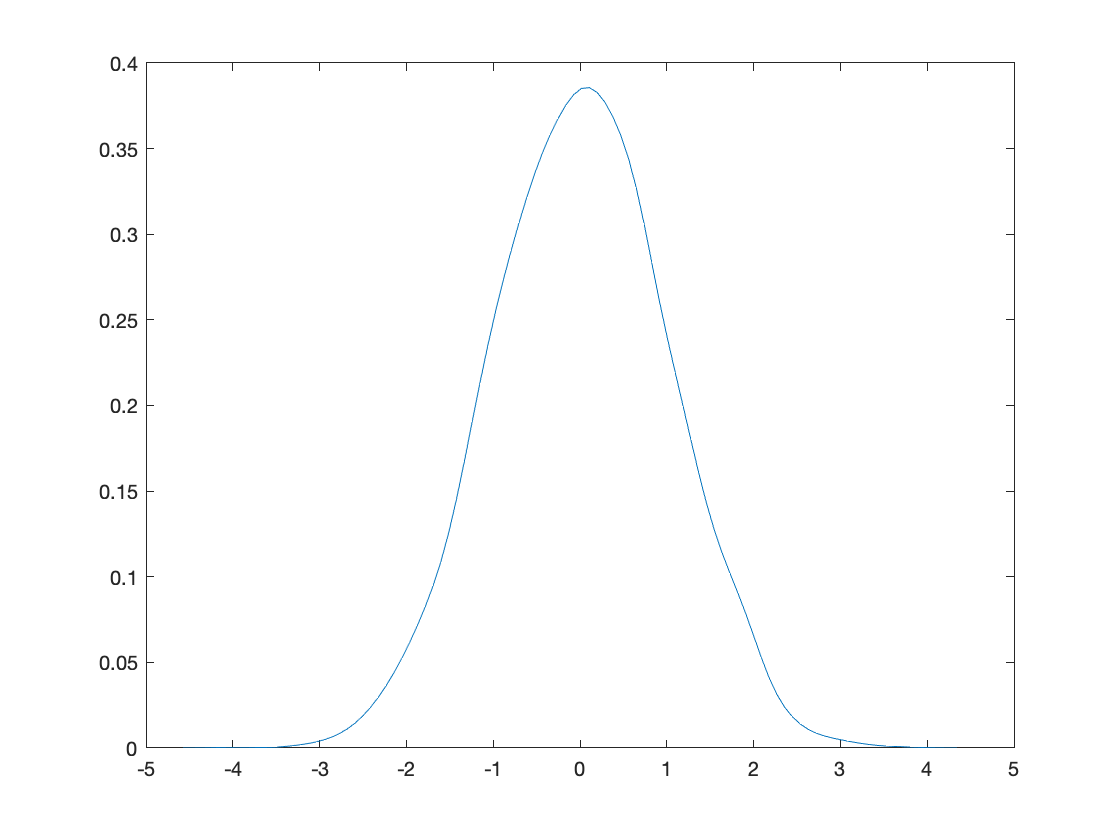

%gwnt = 0.5 * randn(1,4000);
%gwnt2 = 0.5 * randn(1,4000);
[f,xi] = ksdensity(gwnt); 
figure(100)
plot(xi,f);

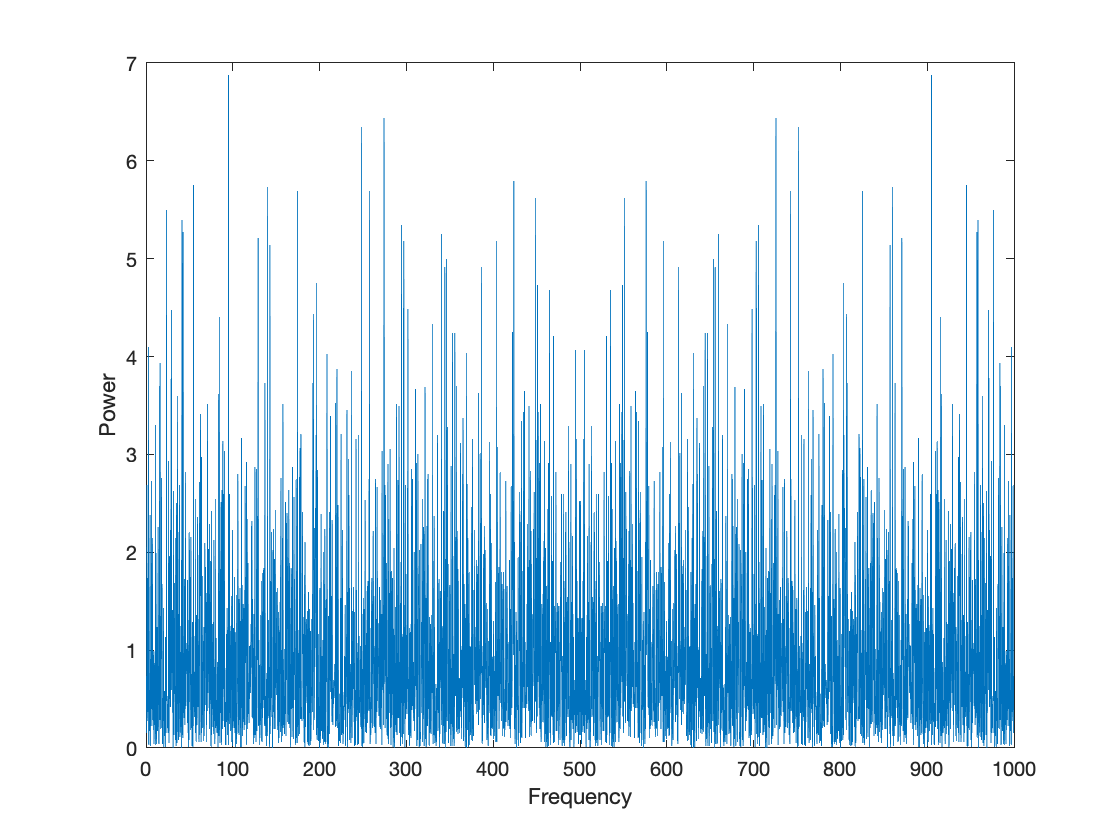


fs = 1000;                                % sample frequency (Hz)
t = 0:1/fs:10-1/fs;                      % 10 second span time vector

y = fft(gwnt);

n = length(gwnt);          % number of samples
f = (0:n-1)*(fs/n);     % frequency range
power = abs(y).^2/n;    % power of the DFT
figure(101)
plot(f,power)
xlabel('Frequency')
ylabel('Power')


deviation_zero=0;
a_corr_gwn_xx_zero=phi_yx2(gwnt,gwnt,deviation_zero);
display('Autocorrelation for a time shift of 0:');

Autocorrelation for a time shift of 0:


display(max(abs(a_corr_gwn_xx_zero)));

     1



display('The power of the signal:');

The power of the signal:


display(std(gwnt));

    0.9986



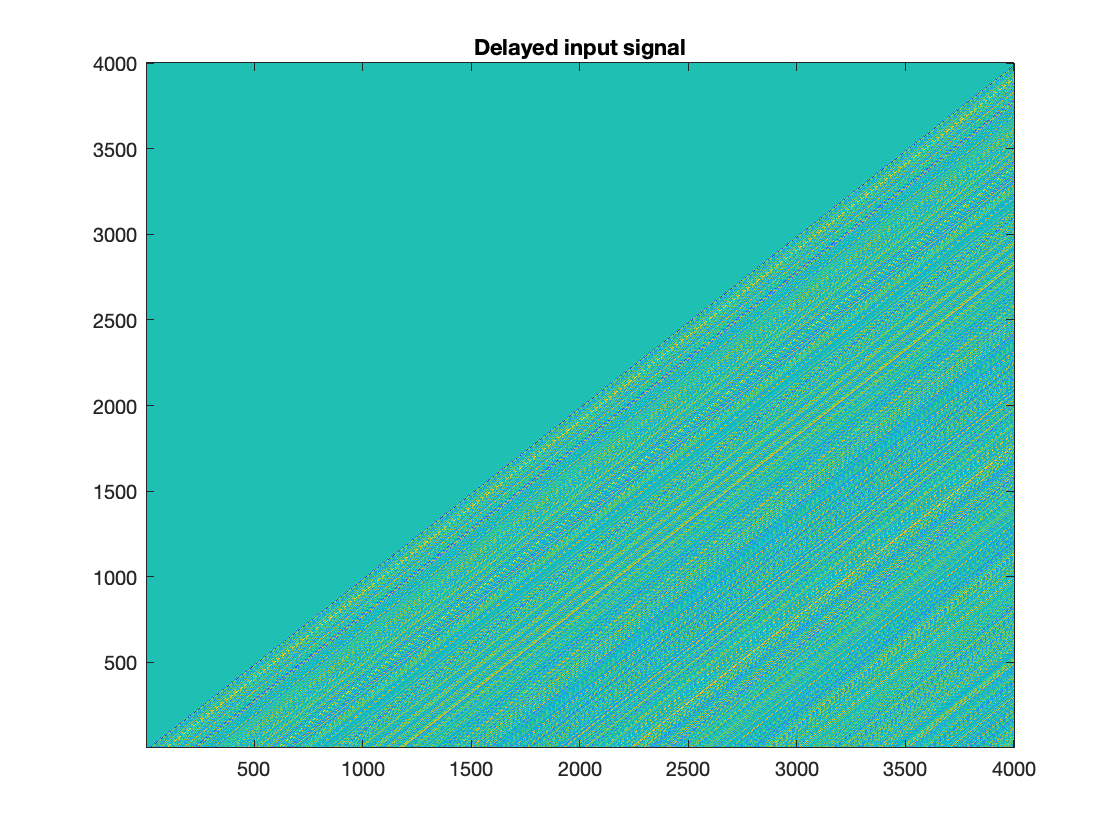


deviation=3999;
a_corr_gwn_xx=phi_yx2(gwnt,gwnt,deviation);

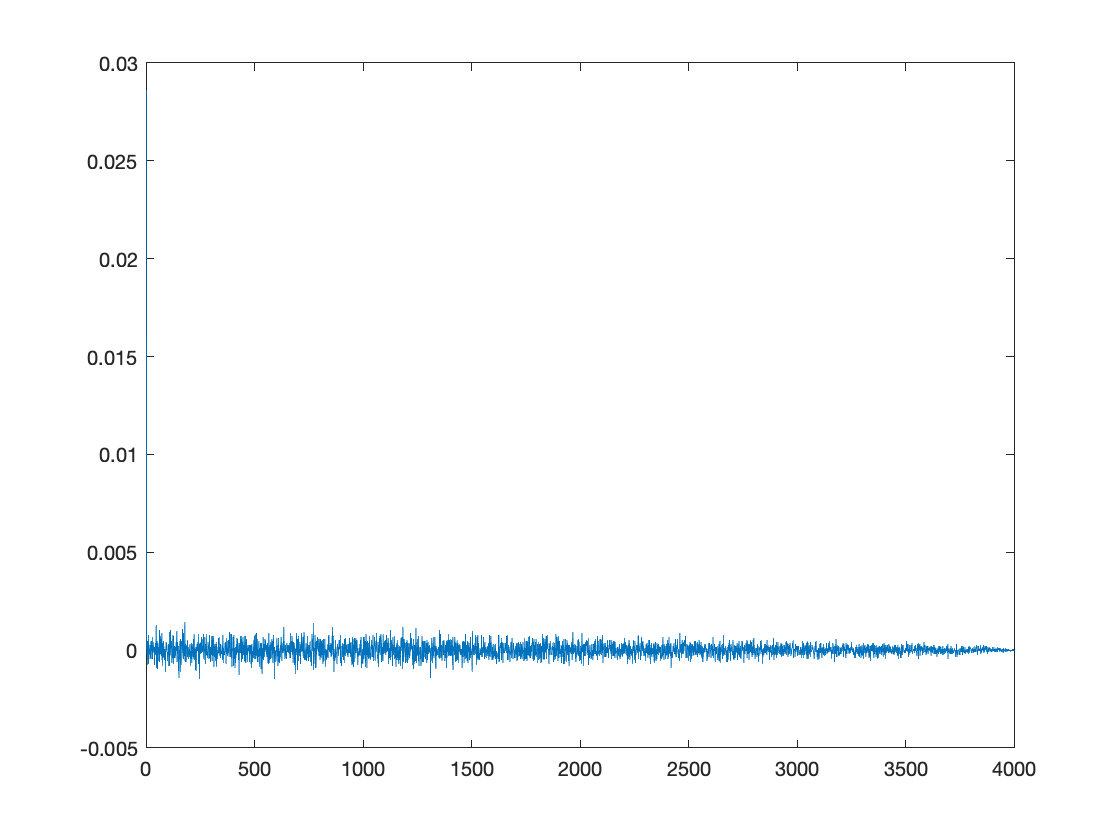

figure(102)
xlim([0 deviation])
plot(a_corr_gwn_xx)

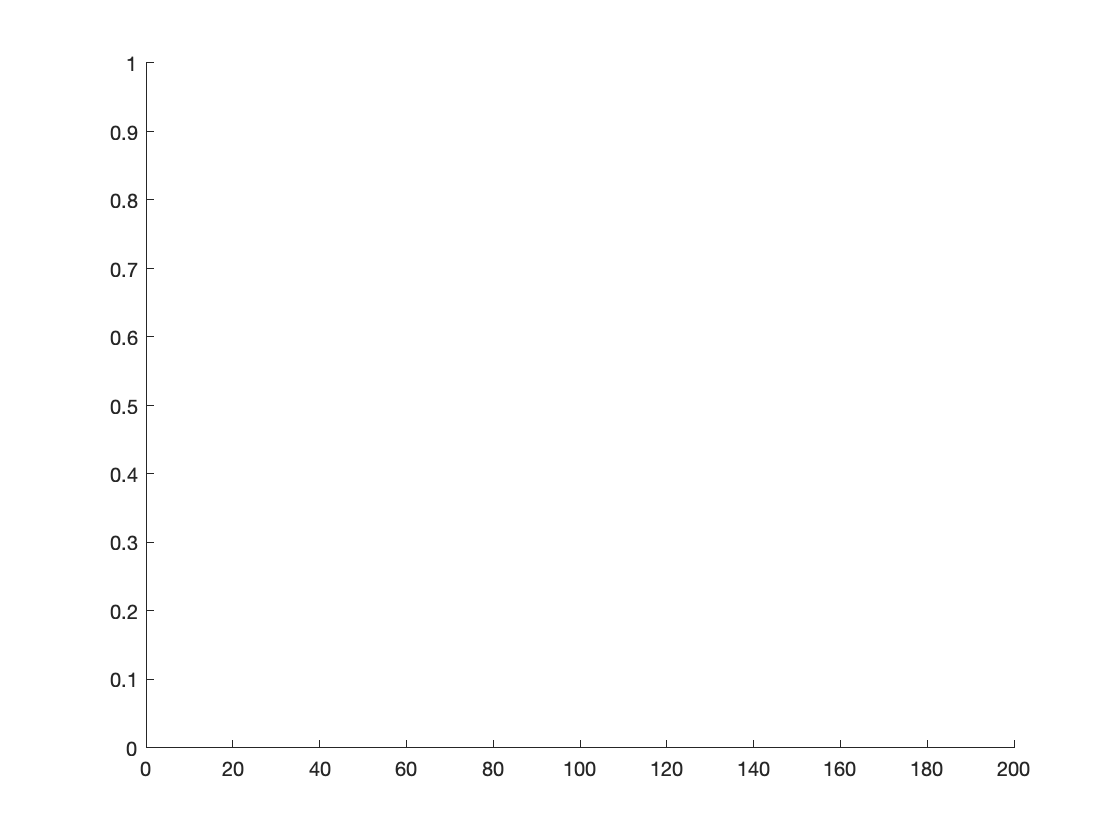

figure(103)
xlim([0 200])

plot(a_corr_gwn_xx(1:200))

In the code above I see that indeed that the amplitude distribution is bell shaped, and that the power distribution is fairly flat. Next to that the I see that the autocorrelation for a time shift of 0 is about equal to the power of the signal, and in a plot of the autocorrelation function it is visible that the amplitude is about 0 everywhere except at 0. 

**Exploring the wiener function**

P = 0.4998

     1



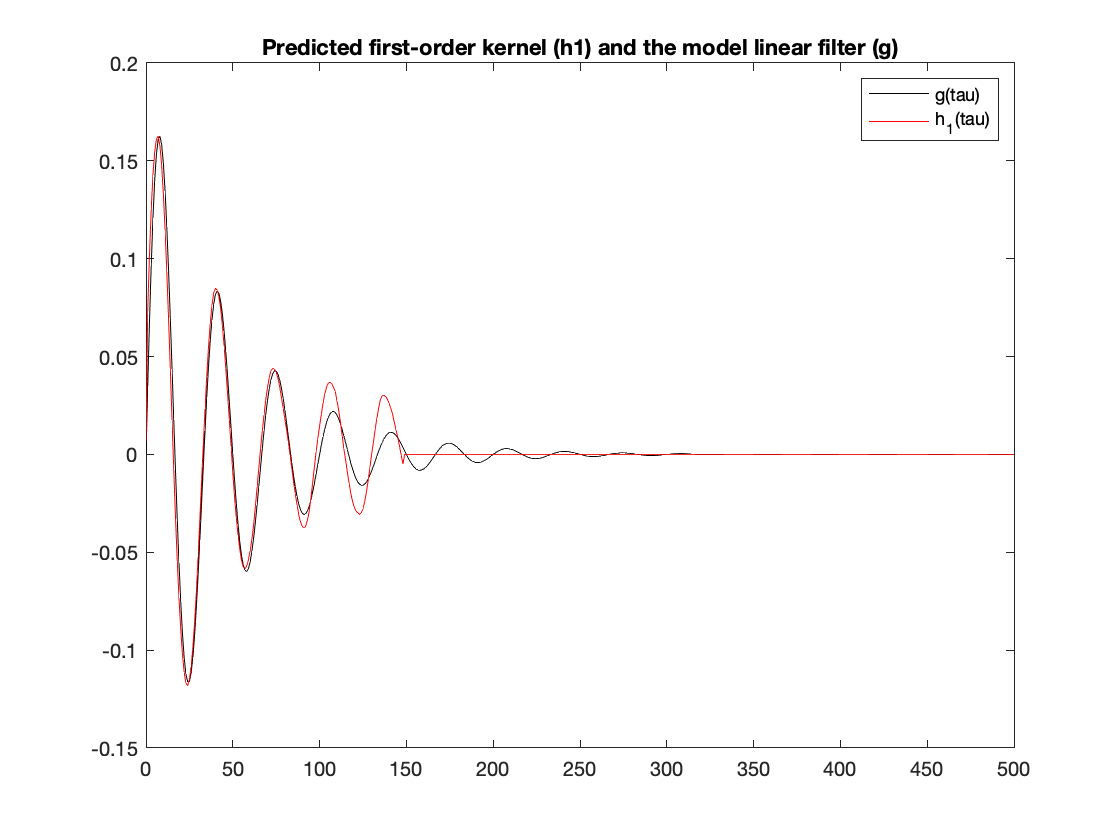

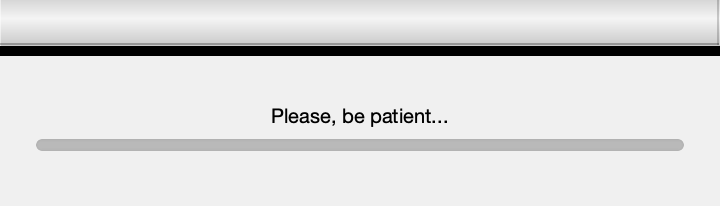

    1.0000



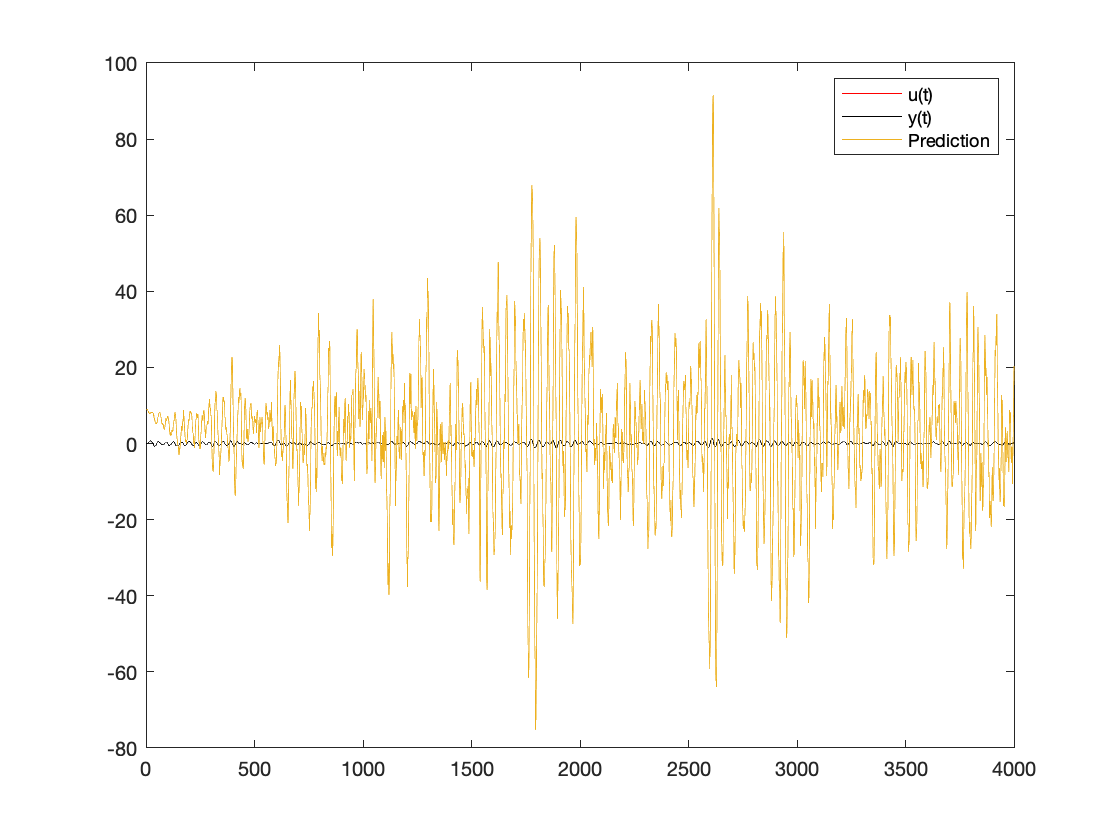

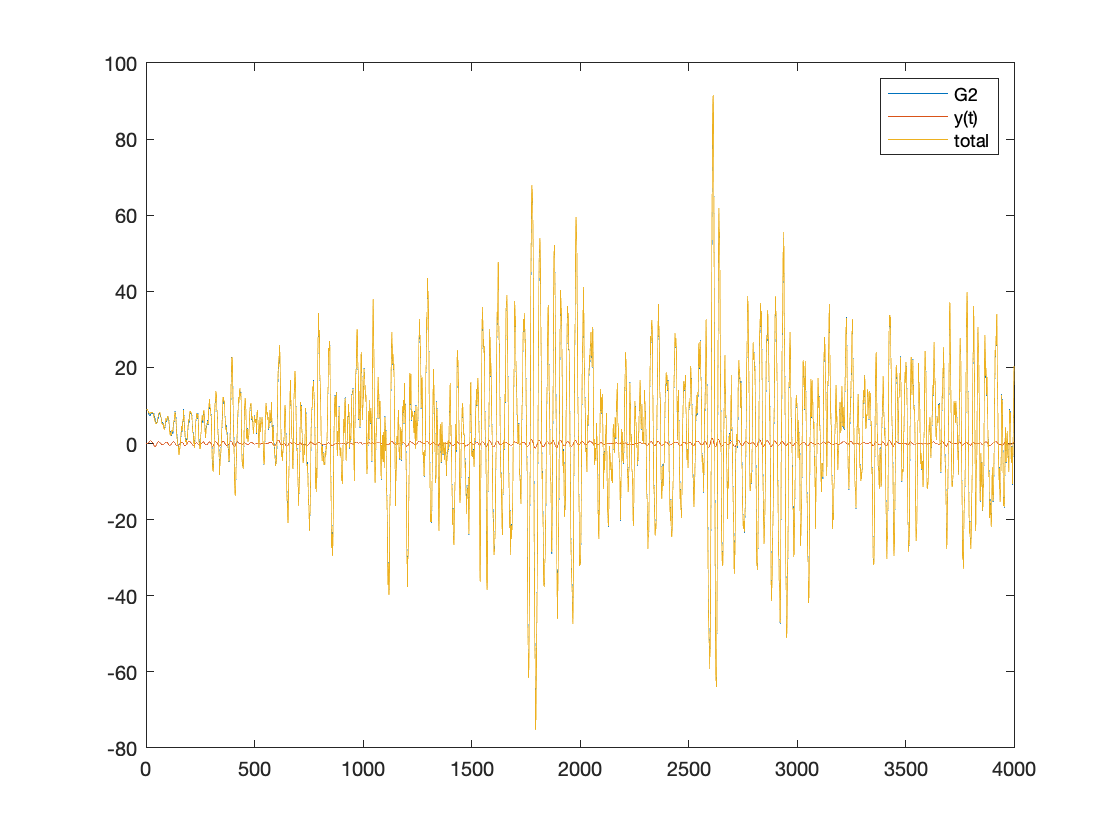

corr total and yt
    1.0000    0.6305
    0.6305    1.0000

corr G2 and yt
    1.0000    0.6188
    0.6188    1.0000

corr G1 and yt
    1.0000    0.9758
    0.9758    1.0000



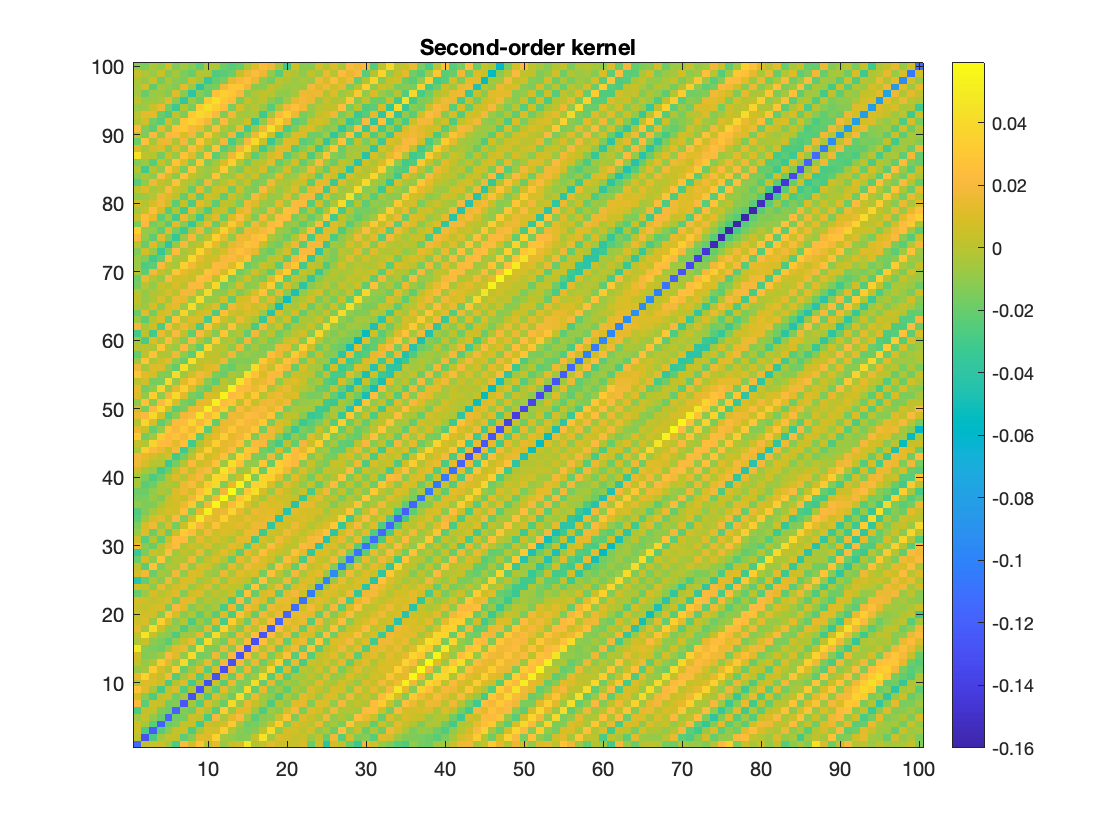

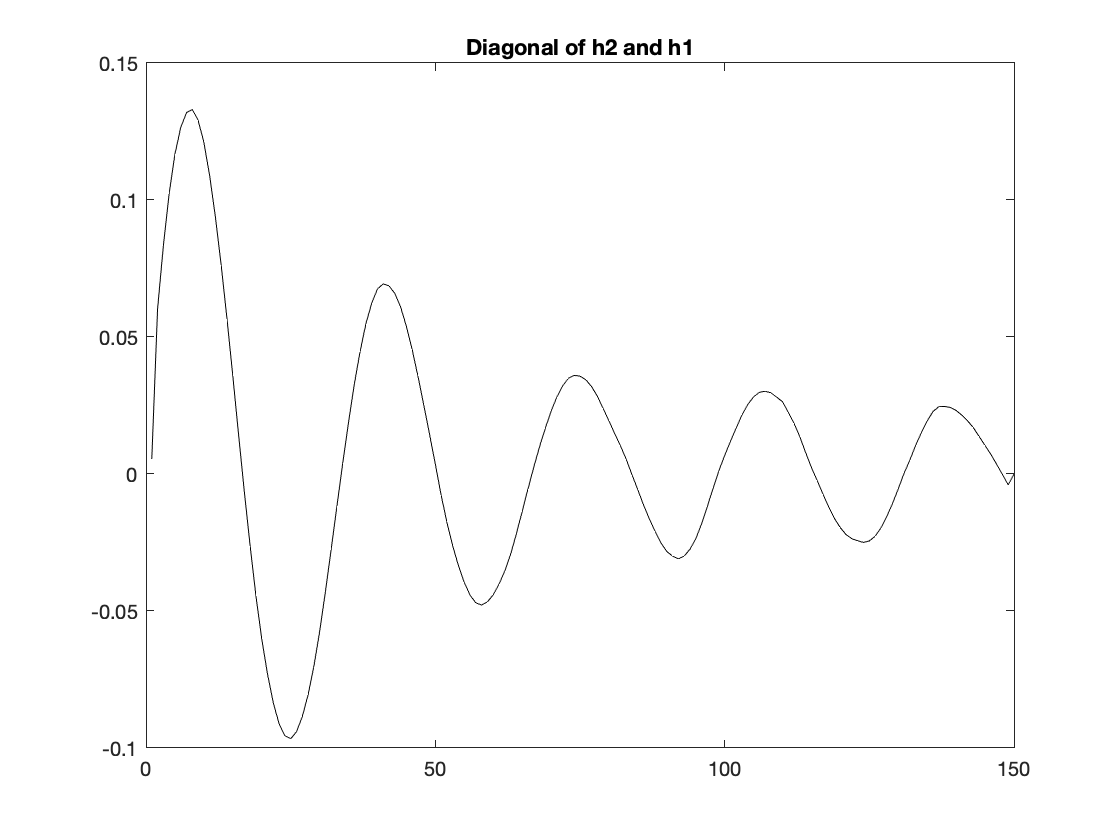

[h0,h1,h2] = wiener(1,0); %(no nonlinearity)

%indeed see that h2 is not very informative for a system without
%nonlinearity
%[h0,h1,h2] = wiener(0,1); %(no linearity)
%indeed see that h1 does not perform well for a nonlinear system
%[h0,h1,h2] = wiener(5,5); %we see that for higher b values the part that the G2 plays becomes larger, as is evident by the higher corrcoef values and something similar for a values and G1
%[h0,h1,h2] = wiener(5,1); %such a difference between the linear and non linear parts requires the sum of the kernals to be adjusted, eg. here G0+G1+0.2*G2 instead of G0+G1+G2

**Test of regstats:**

x=10*randn(100,1);
y=6*(x.^2)+40;
rst=regstats(y,x);
disp(rst);

        source: 'regstats'
             Q: [100×2 double]
             R: [2×2 double]
          beta: [2×1 double]
          covb: [2×2 double]
          yhat: [100×1 double]
             r: [100×1 double]
           mse: 3.9395e+05
       rsquare: 0.0188
    adjrsquare: 0.0088
      leverage: [100×1 double]
        hatmat: [100×100 double]
          s2_i: [100×1 double]
        beta_i: [2×100 double]
      standres: [100×1 double]
       studres: [100×1 double]
       dfbetas: [2×100 double]
         dffit: [100×1 double]
        dffits: [100×1 double]
      covratio: [100×1 double]
         cookd: [100×1 double]
         tstat: [1×1 struct]
         fstat: [1×1 struct]
        dwstat: [1×1 struct]



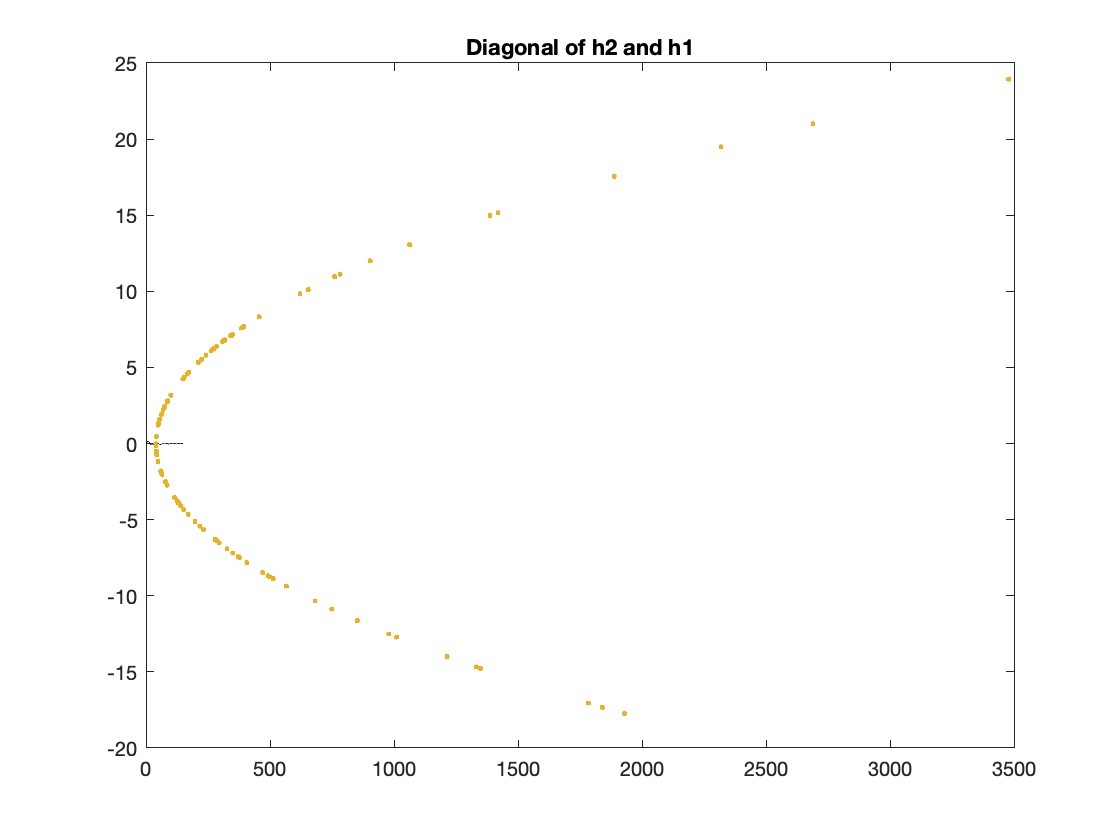

plot(y,x,'.');

**Now that we have played around with the wiener function for a while, and determined how the different parameters seem to work, we can try to work on the actual input files.**

close all;
P = std(gwnt)          % the power of the noise

P = 0.9986


h0=mean(yt);
disp(h0);

    0.0032



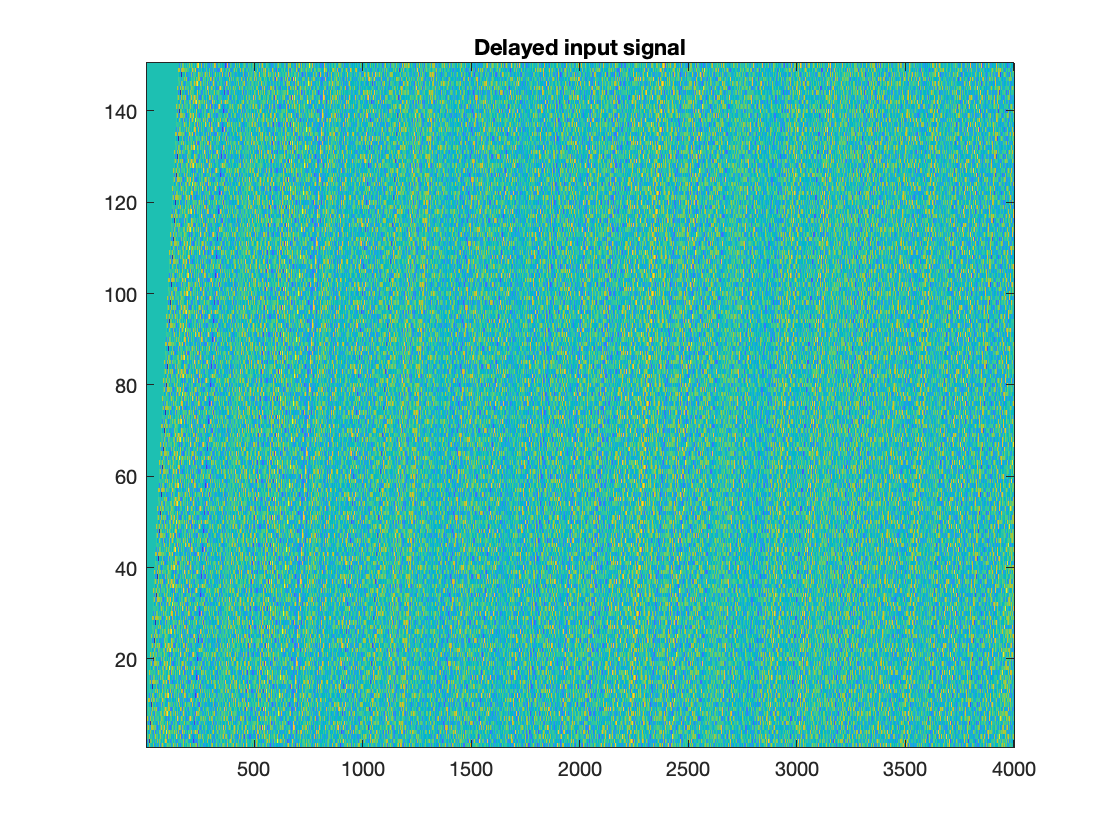

G0 = h0;       % the zero-order Wiener prediction
y0 = yt - G0;      % the Lee-Schetzen method: subtract h0 from the response

%  first order estimate: crosscorrelate
%
fi1 = phi_yx2(y0, gwnt, 150-1);   %first-order kernel

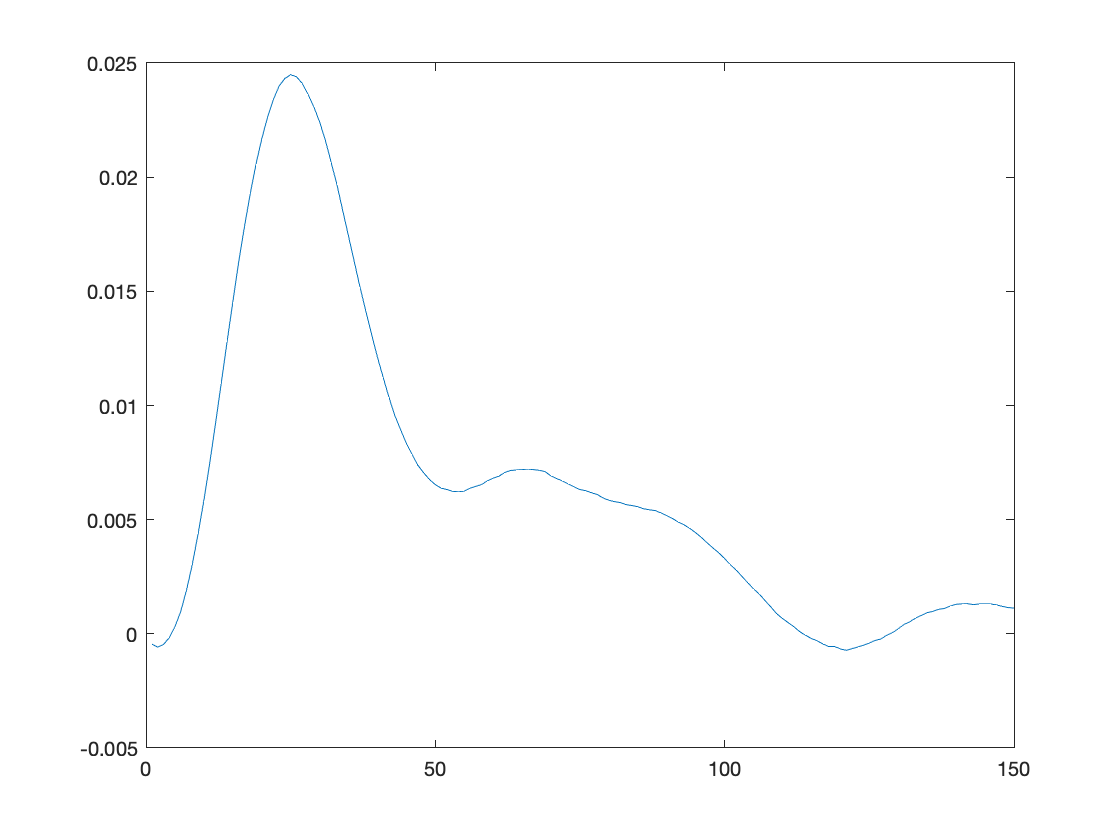

h1=fi1/P;       % only positive tau! 
h1(200:end)=0; %listened to the hint, this reduced the noise a lot indeed
%perhaps 80:end is better
figure(1)
plot(h1);

s=sum((h1)); %get a sum over h1 of one if we take away the absolute value, but get worse results
h1 = h1/s; % normalise the integral to one (this is a "tweaking point.." )
dt=1;
disp(sum(h1)*dt);

     1



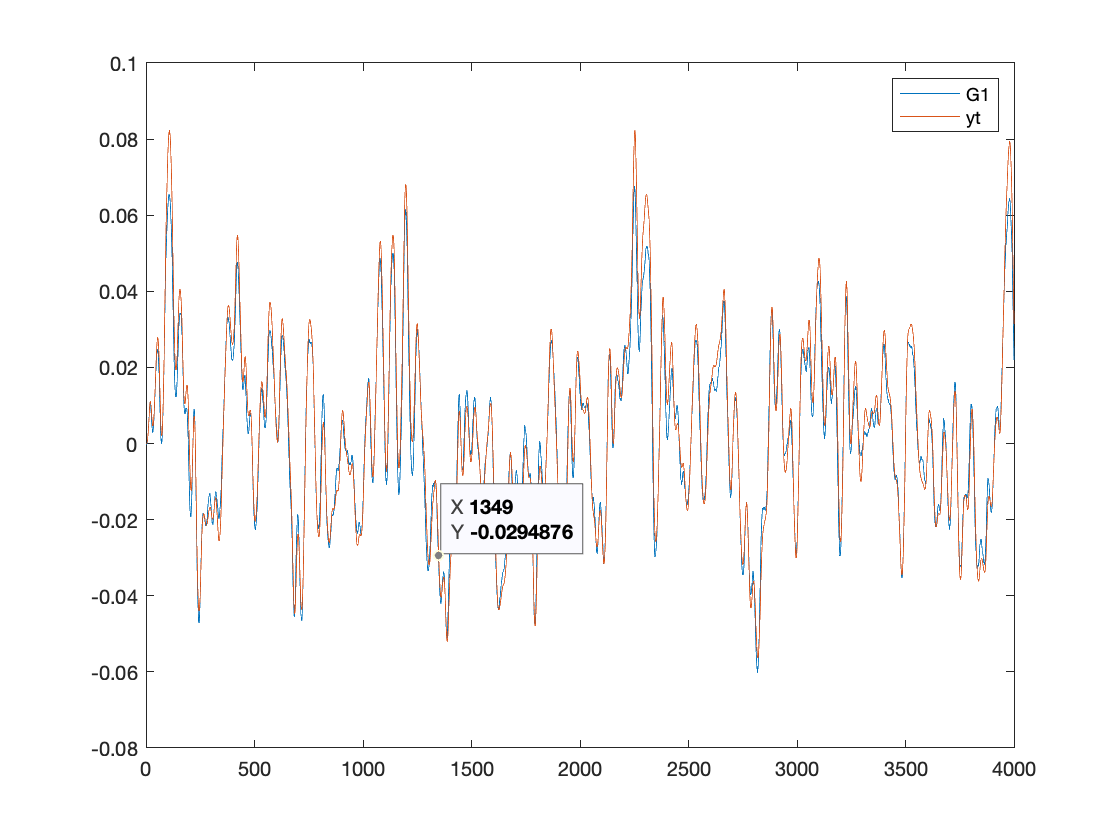


G1 = conv(gwnt, h1);      % 1e order Wiener prediction with the scaled kernel 
G1 = G1(1:length(gwnt));
figure(4)
plot(G1/5); %/5 for very close resemblance to yt 
hold on
plot(yt);
%plot(y1);
legend('G1','yt');
hold off

y1 = yt - G0 - G1;    % residue, corrected for G0 and G1

%
%    second order kernel: 3rd-order cross-correlation
%
fi2=phi_yxx2(y1, gwnt, 105); %can decrease the slope of the regression by decreasing the third parameter

h2=fi2/(2*P^2);         % the 2nd order Wiener kernel: only positive tau1, tau2 
%h2(1:200,1:200)=0;
s = sum(sum((h2)));  % total integral of the kernel
h2 = h2/s;              % normalize the kernel to one   
disp(sum(sum(h2))*dt);

     1



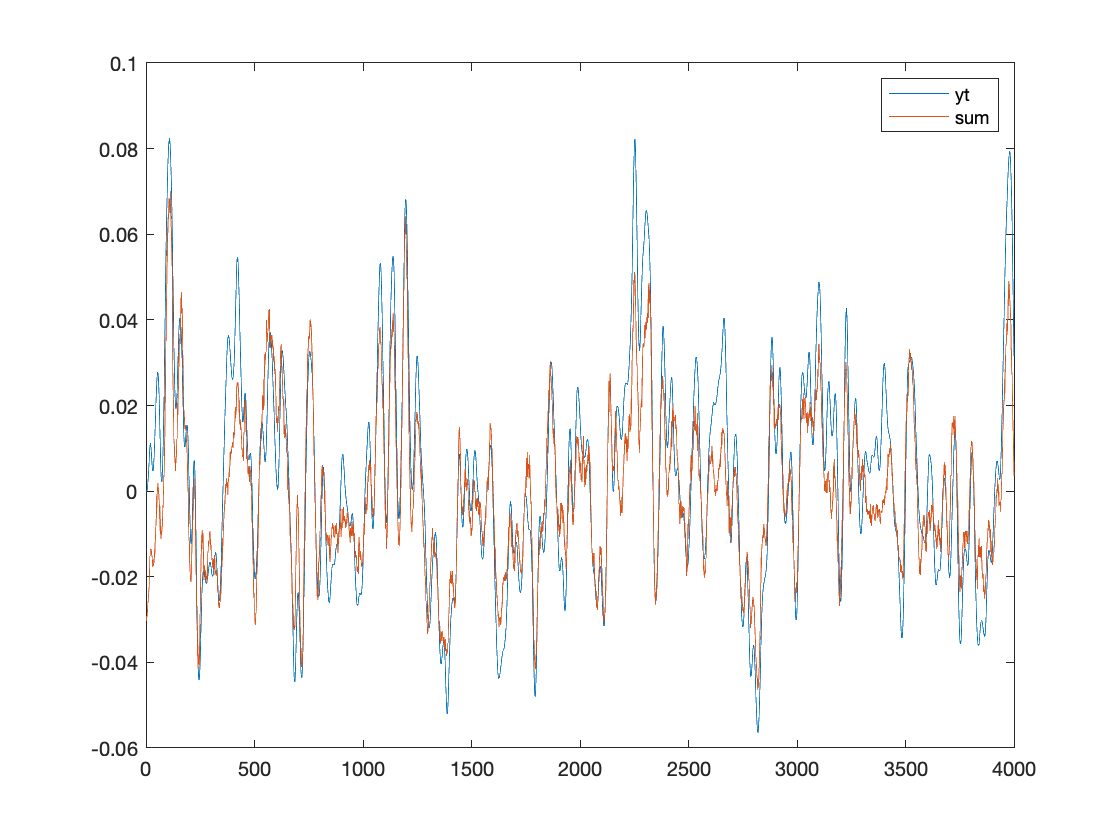


G2 = convh2xx(h2,gwnt,P);      % 1e order Wiener prediction with the scaled kernel 
G2=G2(1:length(gwnt));
figure(4)
plot(yt); 
hold on
%plot(G2);
plot((G0+G1+G2)/12.5);
legend('yt','sum');
%legend('G2','yt','sum');
hold off

disp("corr total and yt");

corr total and yt


disp(corrcoef((G0+G1+G2),yt));

    1.0000    0.9095
    0.9095    1.0000



disp("corr G2 and y1");

corr G2 and y1


disp(corrcoef((G2),y1));

    1.0000   -0.7242
   -0.7242    1.0000



disp("corr G1 and y0");

corr G1 and y0


disp(corrcoef((G1),y0));

    1.0000    0.9888
    0.9888    1.0000



disp("corr G1 and yt");

corr G1 and yt


disp(corrcoef((G0+G1),y0)); %very high in the case of G1/5

    1.0000    0.9888
    0.9888    1.0000



disp(mean(abs(yt-((G0+G1+G2)/10))));

    0.0083



disp(std(abs(yt-((G0+G1+G2)/10))));

    0.0069



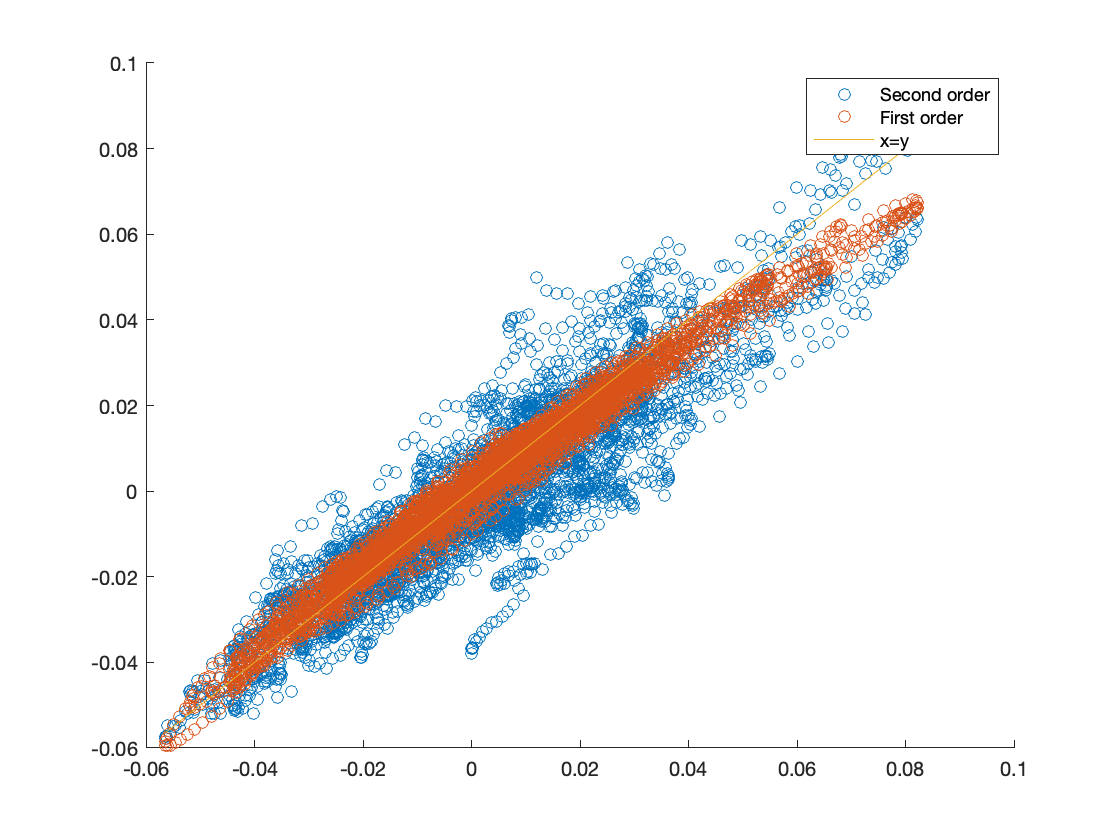

x_plt=linspace(min(yt),max(yt),10);
figure(5);
scatter(yt,(G0+G1+G2)/10);
hold on
scatter(yt,(G0+G1)/5);
plot(x_plt,x_plt);
legend('Second order','First order','x=y');


P = std(input1) 

P = 0.0160

h01=mean(output1);
G01 = h01; 
G11 = conv(input1, h1); 
G11=G11(1:length(input1));
G21 = convh2xx(h2,input1,P,1);
%G21=G21(1:length(gwnt));
disp("corr total and output1");

corr total and output1


disp(corrcoef((G01+G11+G21),output1));

    1.0000    0.9749
    0.9749    1.0000



disp(corrcoef((G01+G11),output1));

    1.0000    0.9753
    0.9753    1.0000



disp(mean(abs(output1-((G01+G11+G21)/10))));

   3.6204e-04



disp(std(abs(output1-((G01+G11+G21)/10))));

   2.6980e-04



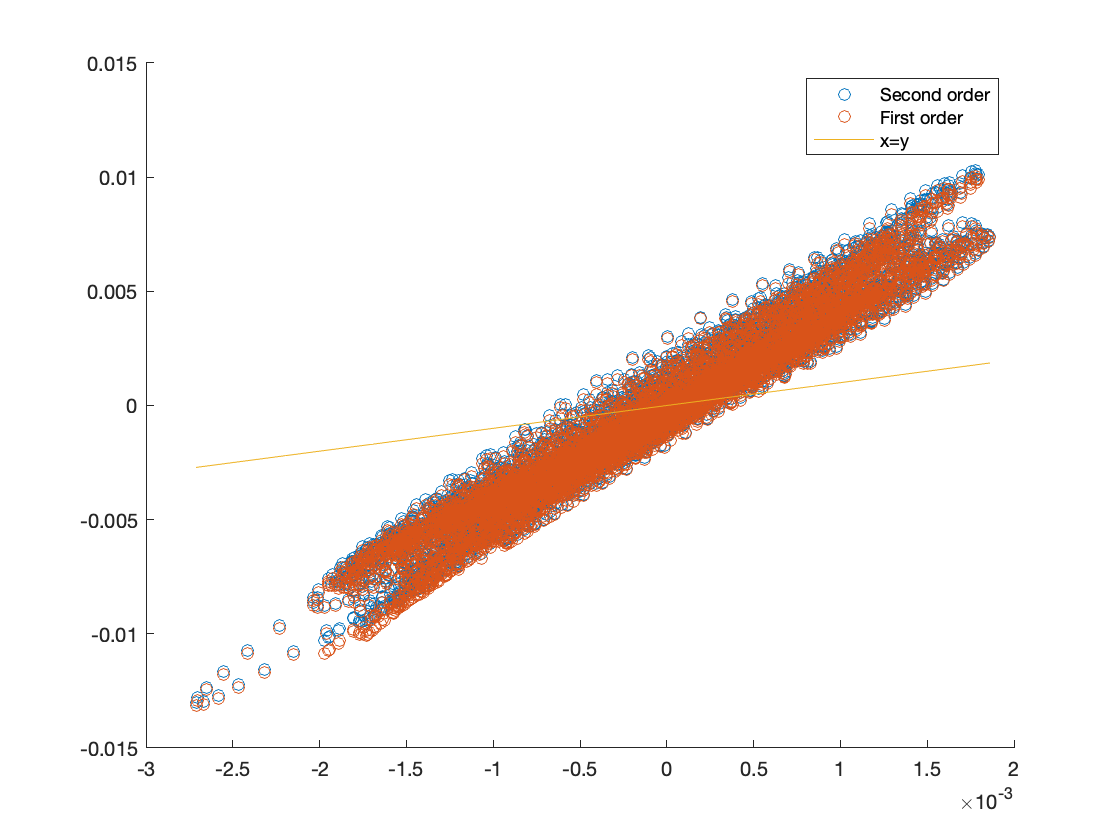

x_plt=linspace(min(output1),max(output1),10);
figure(6);
scatter(output1,(G01+G11+G21));
hold on
scatter(output1,(G01+G11));
plot(x_plt,x_plt);
legend('Second order','First order','x=y');

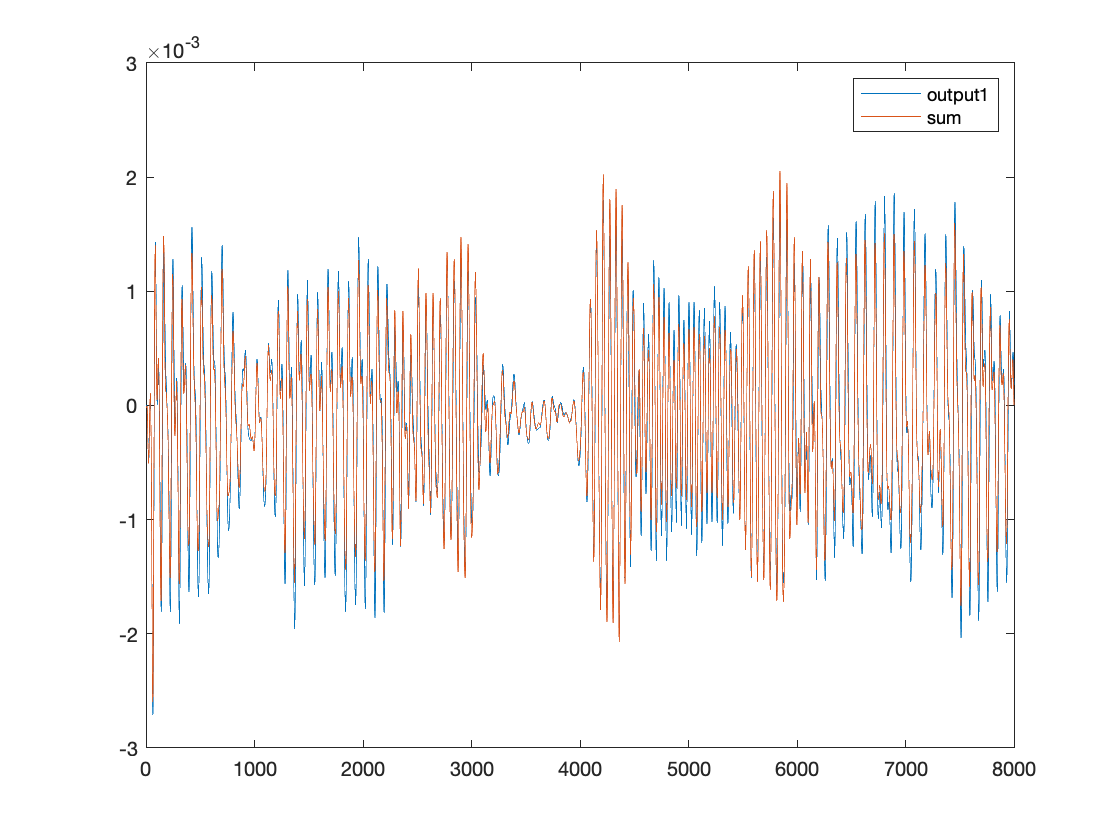

figure(7)
plot(output1); 
hold on
%plot(G2);
plot((G01+G11+G21)/5);
legend('output1','sum');
%legend('G2','yt','sum');
hold off


P = std(input2)

P = 0.0091

h02=mean(output2);
G02 = h02; 
G12 = conv(input2, h1); 
G12=G12(1:length(input2));
G22 = convh2xx(h2,input2,P,1);
%G21=G21(1:length(gwnt));
disp("corr total and output2");

corr total and output2


disp(corrcoef((G02+G12+G22),output2));

    1.0000    0.9669
    0.9669    1.0000



disp(corrcoef((G02+G12),output2));

    1.0000    0.9676
    0.9676    1.0000



disp(mean(abs(output2-((G02+G12+G22)/10))));

   1.3167e-04



disp(std(abs(output2-((G02+G12+G22)/10))));

   1.5049e-04



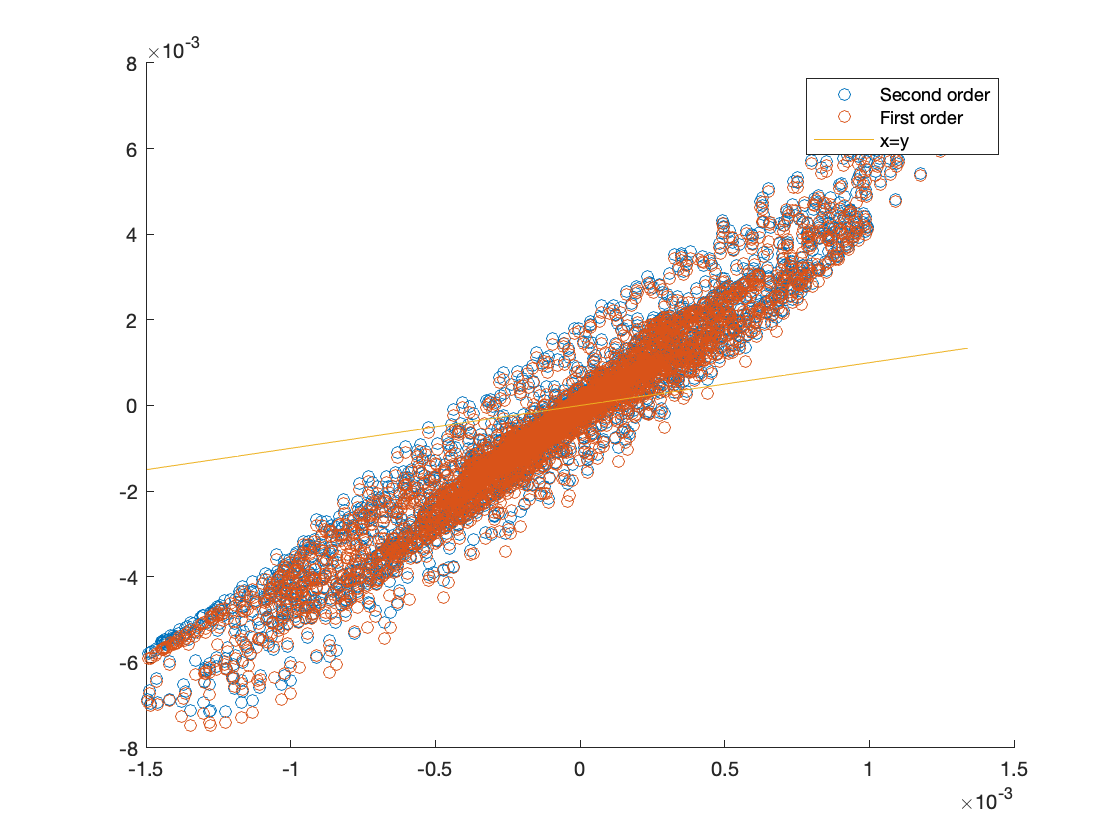

x_plt=linspace(min(output2),max(output2),10);
figure(8);
scatter(output2,(G02+G12+G22));
hold on
scatter(output2,(G02+G12));
plot(x_plt,x_plt);
legend('Second order','First order','x=y');

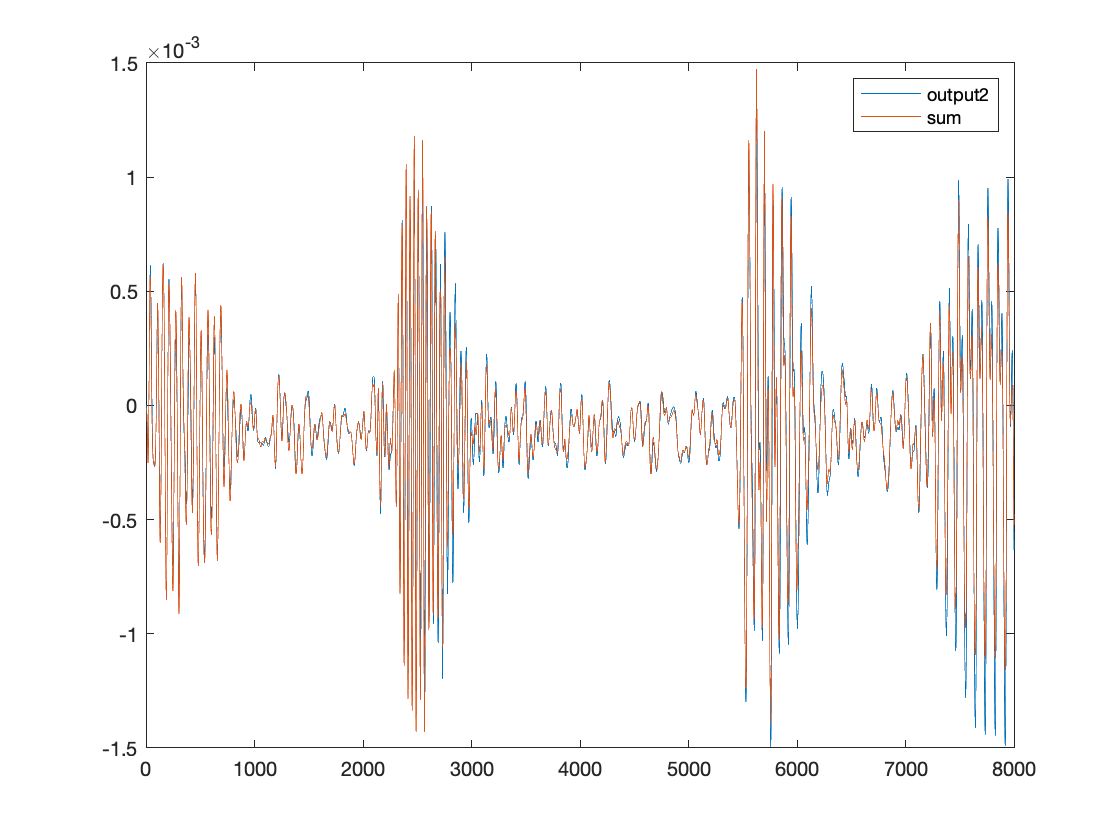

figure(9)
plot(output2); 
hold on
%plot(G2);
plot((G02+G12+G22)/5);
legend('output2','sum');
%legend('G2','yt','sum');
hold off


P = std(input3)

P = 0.0105

h03=mean(output3);
G03 = h03; 
G13 = conv(input3, h1); 
G13=G13(1:length(input3));
G23 = convh2xx(h2,input3,P,1);
%G21=G21(1:length(gwnt));
disp("corr total and output3");

corr total and output3


disp(corrcoef((G03+G13+G23),output3));

    1.0000    0.9658
    0.9658    1.0000



disp(corrcoef((G03+G13),output3));

    1.0000    0.9662
    0.9662    1.0000



disp(mean(abs(output3-((G03+G13+G23)/10))));

   2.0822e-04



disp(std(abs(output3-((G03+G13+G23)/10))));

   2.0130e-04



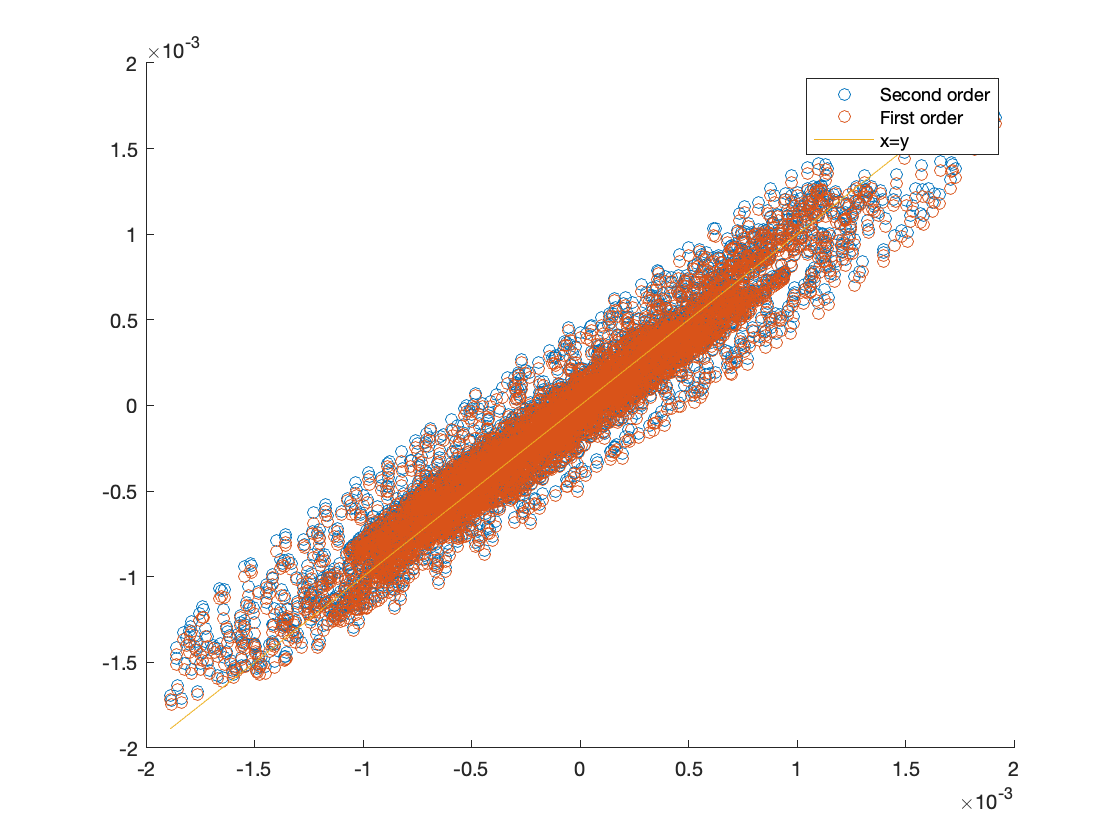

x_plt=linspace(min(output3),max(output3),10);
figure(10);
scatter(output3,(G03+G13+G23)/5);
hold on
scatter(output3,(G03+G13)/5);
plot(x_plt,x_plt);
legend('Second order','First order','x=y');

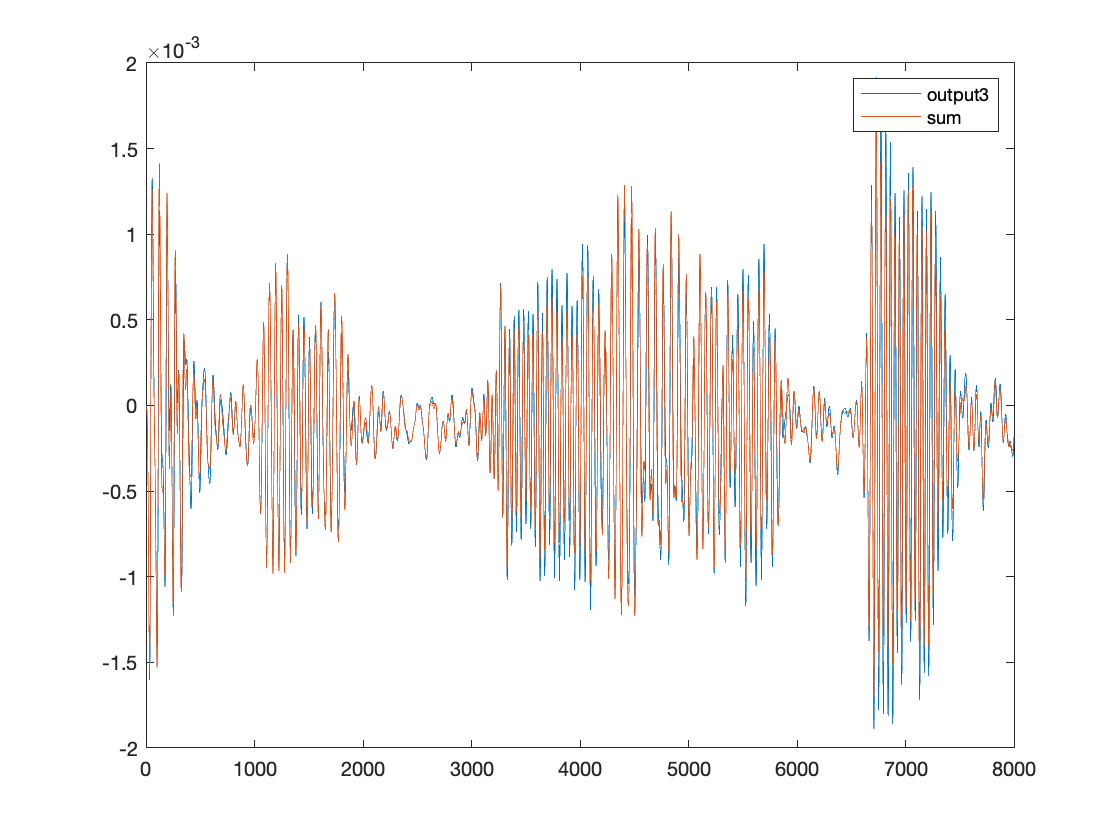

figure(11)
plot(output3); 
hold on
%plot(G2);
plot((G03+G13+G23)/5);
legend('output3','sum');
%legend('G2','yt','sum');
hold off